watersgedImageProcessingTest_1

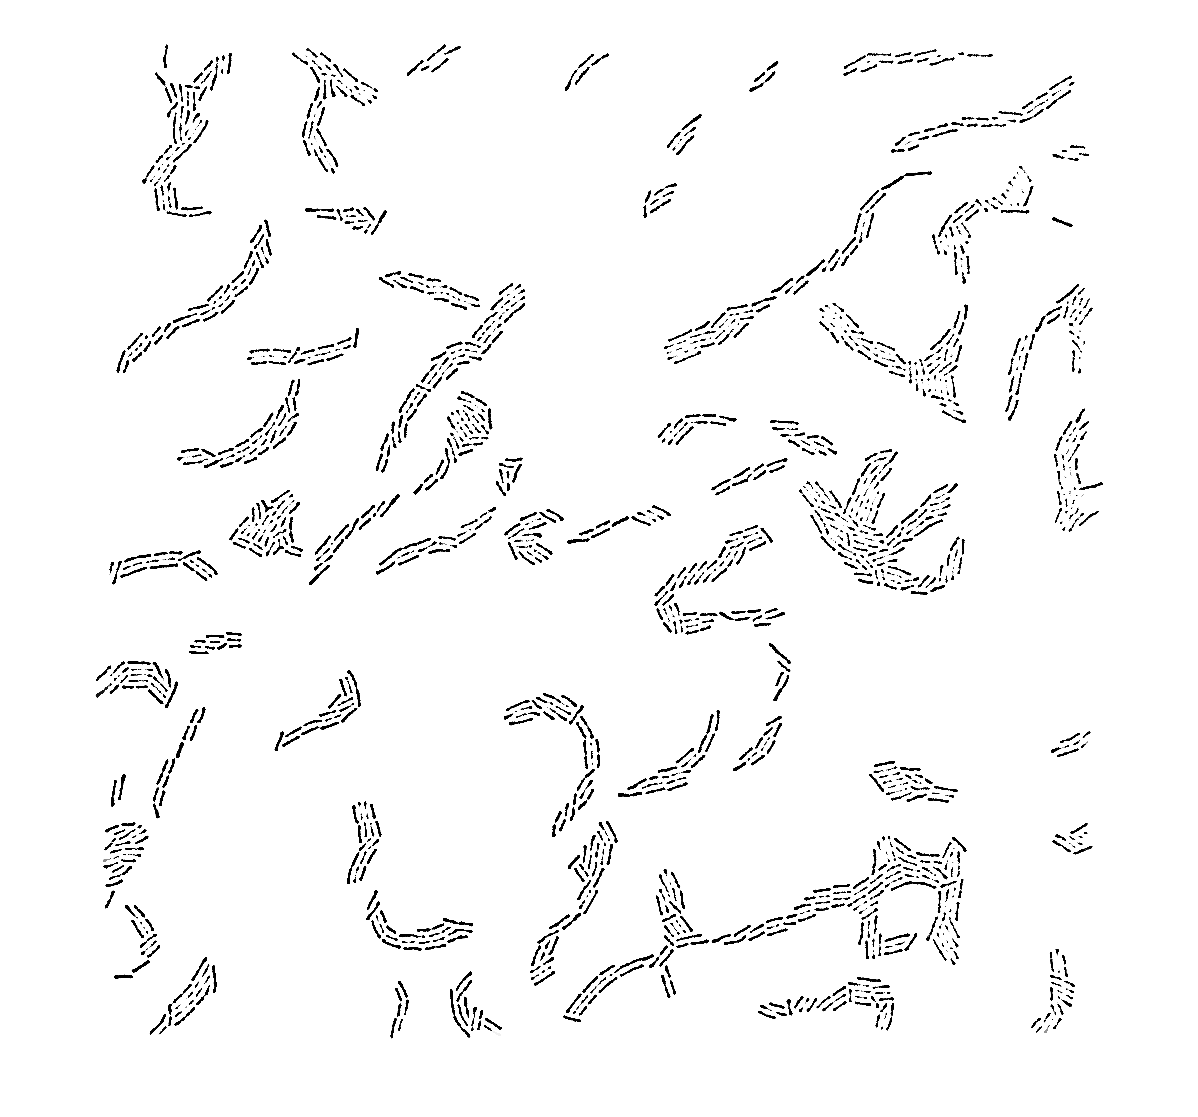

% image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');

% I_eq=image;
% [bw,~]=myImageProcessing_cBFys(I_eq,'w');
% imshow(bw)
% 
% 
% 
% bw2=bw;
% bw3=bw2;
% bw4=bw3;
% bw4_perim = bwperim(bw4);
% imshow(bw4_perim)
% overlay1 = imoverlay(I_eq, bw4_perim, [.3 1 .3]);
% imshow(overlay1)
% 
% 
% fImg=locmax2d(image, [101,101], 1);
% overlay1 = imoverlay(image, logical(fImg), [.3 1 .3]);
% imshow(overlay1)
% mask_em=fImg&bw;
% imshow(mask_em)

% % mask_em=imerode(bw,ones(3));
% overlay2 = imoverlay(I_eq, bw4_perim | mask_em, [.3 1 .3]);
% imshow(overlay2)
% 
% I_eq_c = imcomplement(I_eq);
% imshow(I_eq_c)
% 
% I_mod = imimposemin(I_eq_c, ~bw4 | mask_em);
% imshow(I_mod,[0,50])
% 
% 
% L = watershed(I_mod);
% imshow(L)
% imshow(label2rgb(L))
% L_1=imbinarize(L,2/2^16);
% imshow(L_1)

I_mod1 = imimposemin(I_eq_c, mask_em);
imshow(I_mod1,[0,50])

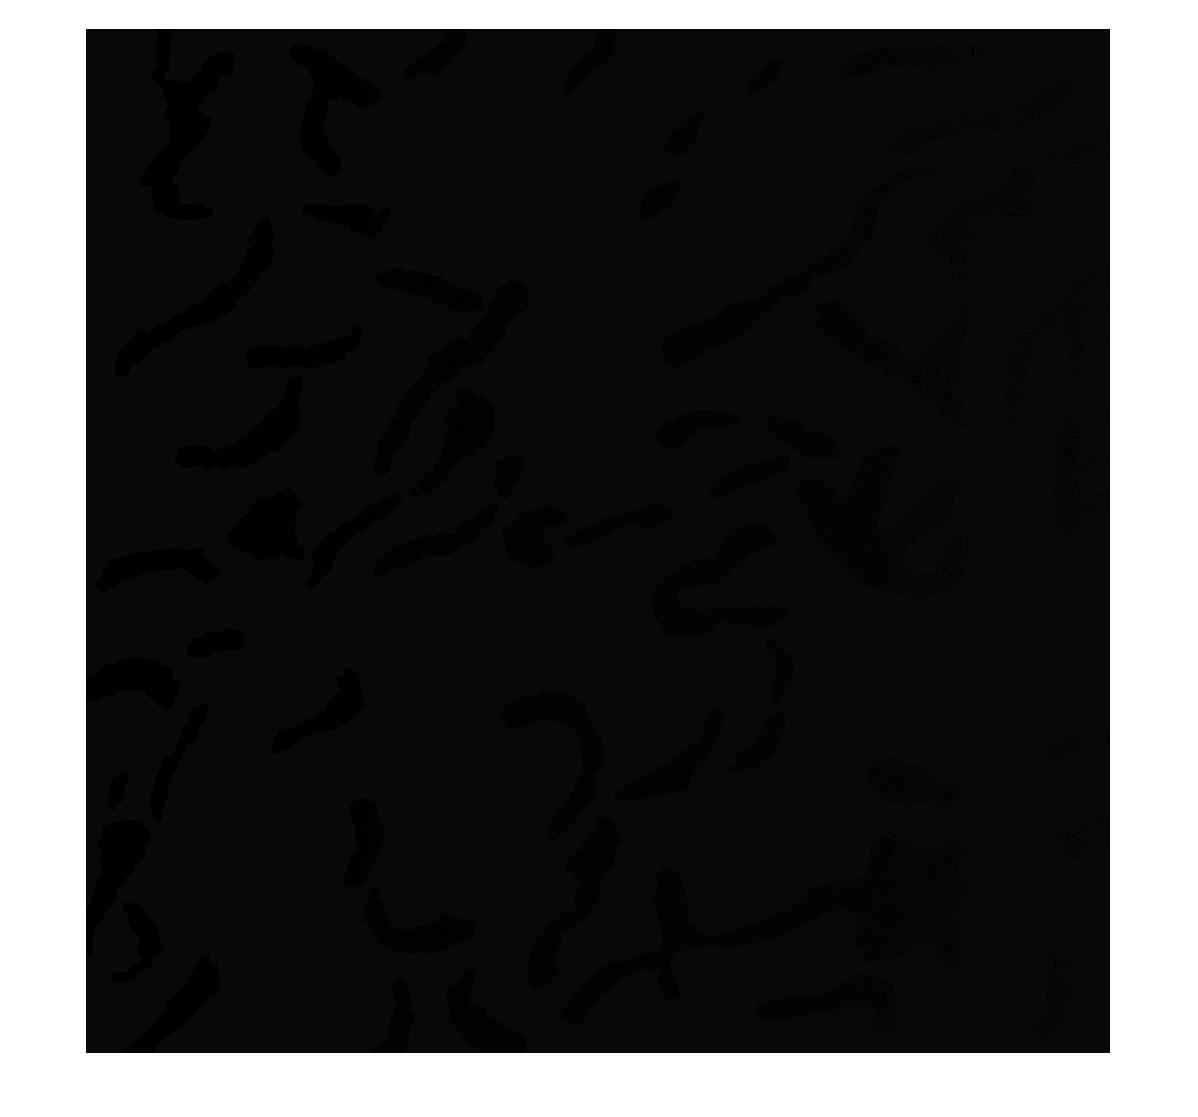


L1 = watershed(I_mod1);
imshow(L1)

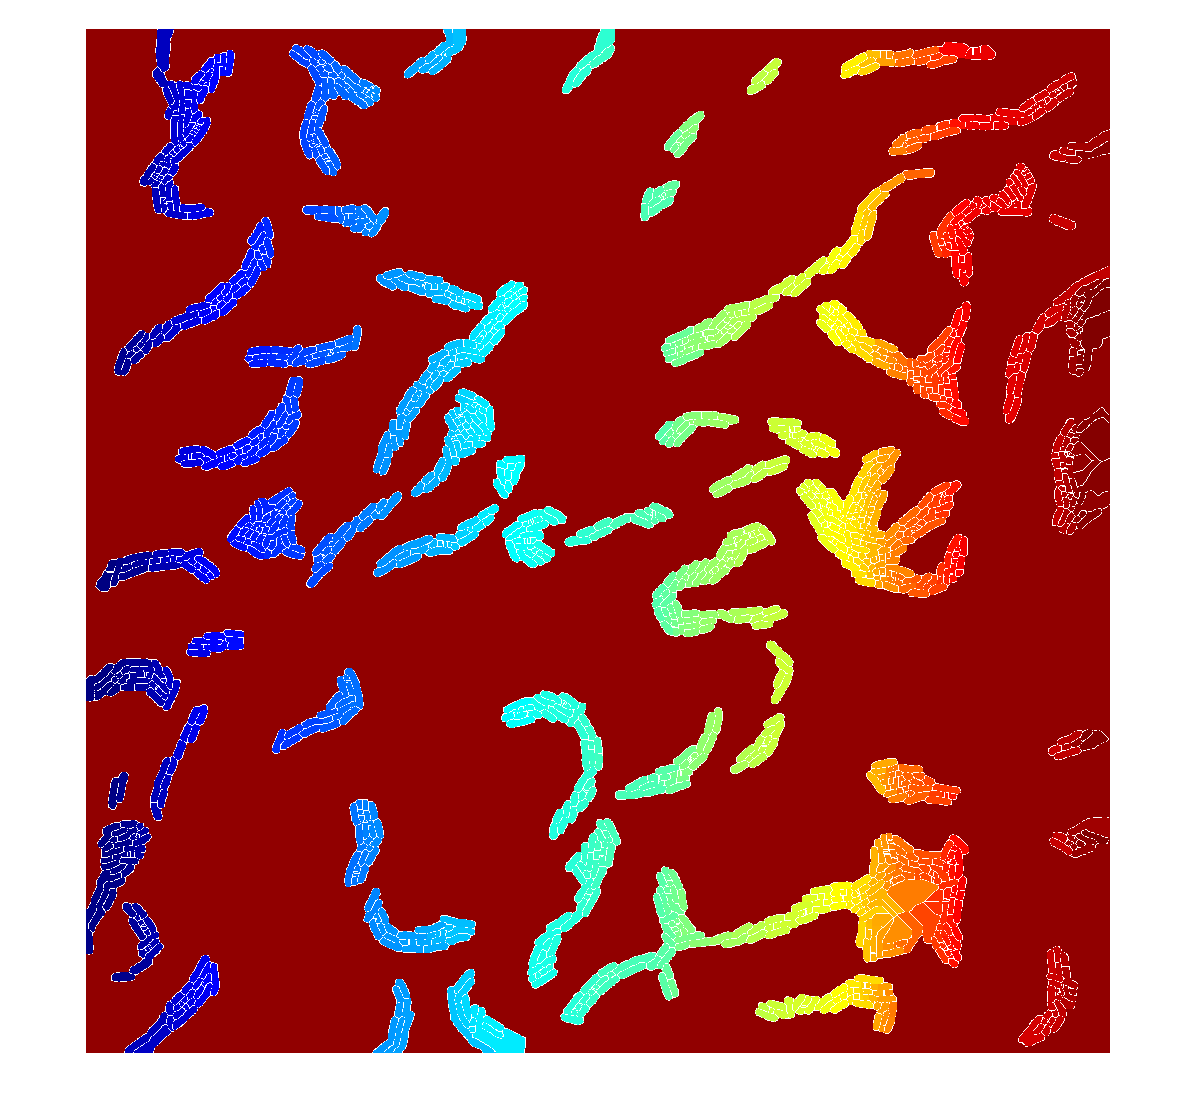

imshow(label2rgb(L1))

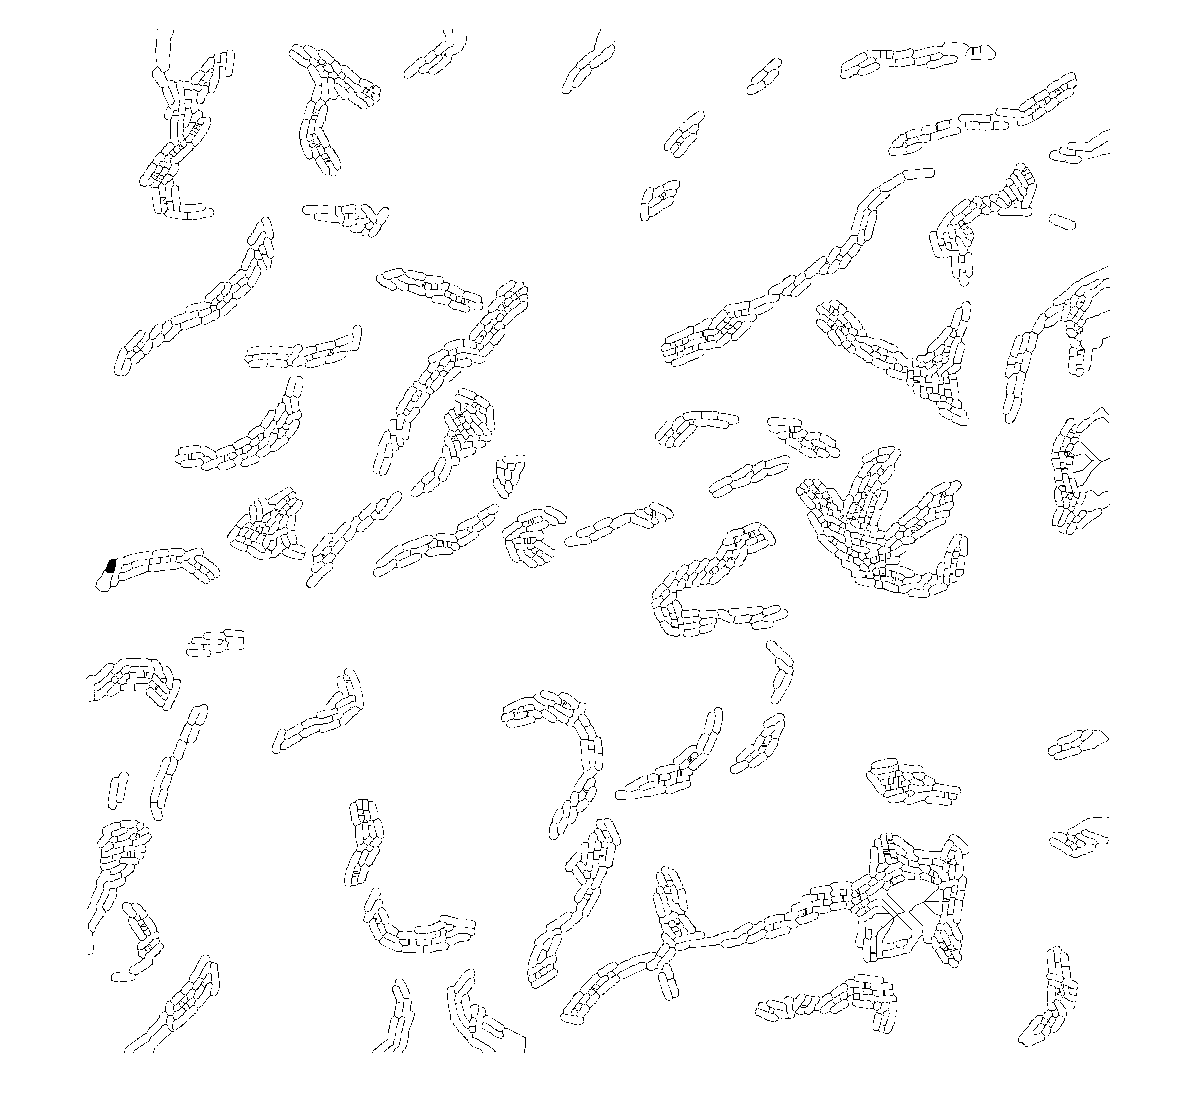

L1_1=imbinarize(L1,2/2^16);
imshow(L1_1)


% oversegmented
